# Create and Customize Stairstep Graphs

`stairs` produces a stairstep graph.

## Create Data

Use a simple `sin` function in a helper function to generate vectors to illustrate use of the `stairs` function.

[x,y1,y2] = createData();

## Basic Stairstep Graph

The stairstep graph illustrates the discrete nature of the data generated using the helper function.

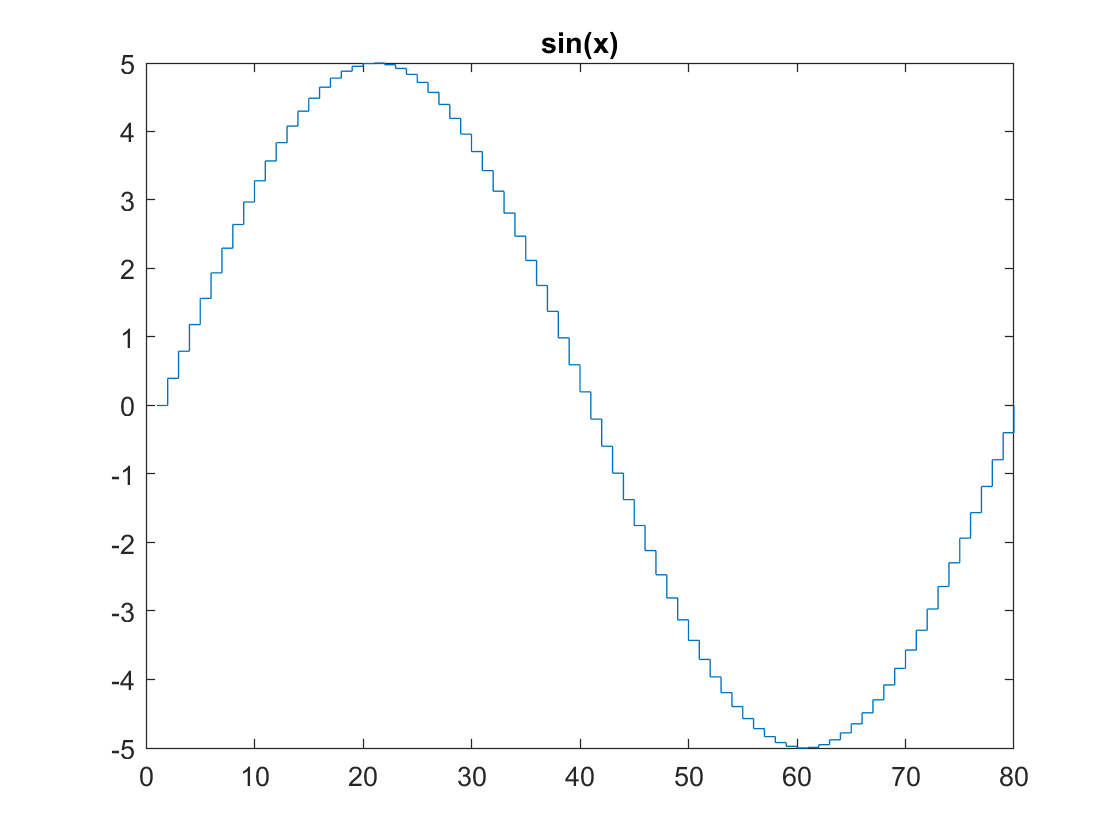

stairs(y1);
title("sin(x)")

## Customization

### Specify Line and Marker Properties

Line and Marker properties such as *LineWidth, Marker*, and *MarkerFaceColor *can be customized using Name, Value pairs in the function call. These can make the graph more visually appealing.

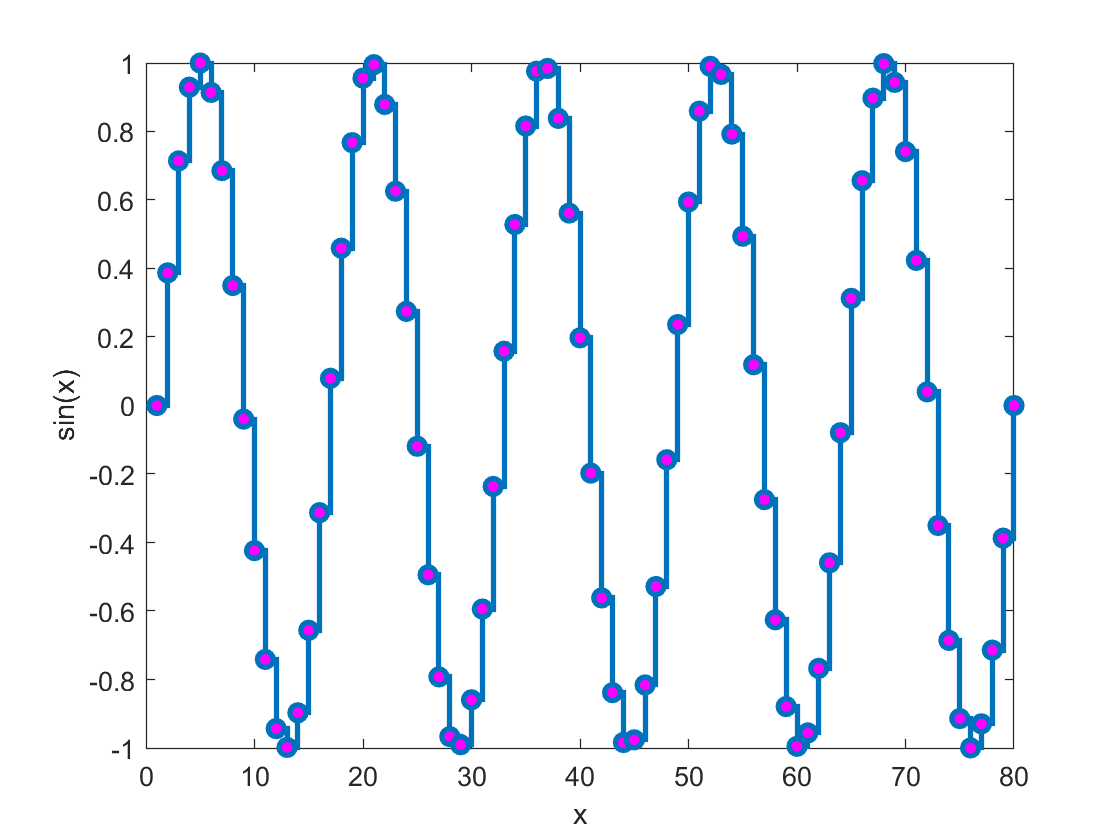

LineWidth = 2;
MarkerType = 'o';
MarkerFaceColor = 'm';

figure
s = stairs(y2,...
    "LineWidth",LineWidth,...           % Specify the line width
    "Marker", MarkerType,...            % Specify the marker shape
    "MarkerFaceColor", MarkerFaceColor);% Specify the marker fill color
xlabel("x")
ylabel("sin(x)")

### Specifying Axes for Stairstep Plots

Use the tiledlayout and nexttile functions to display a tiled layout of 2 stairstep plots.

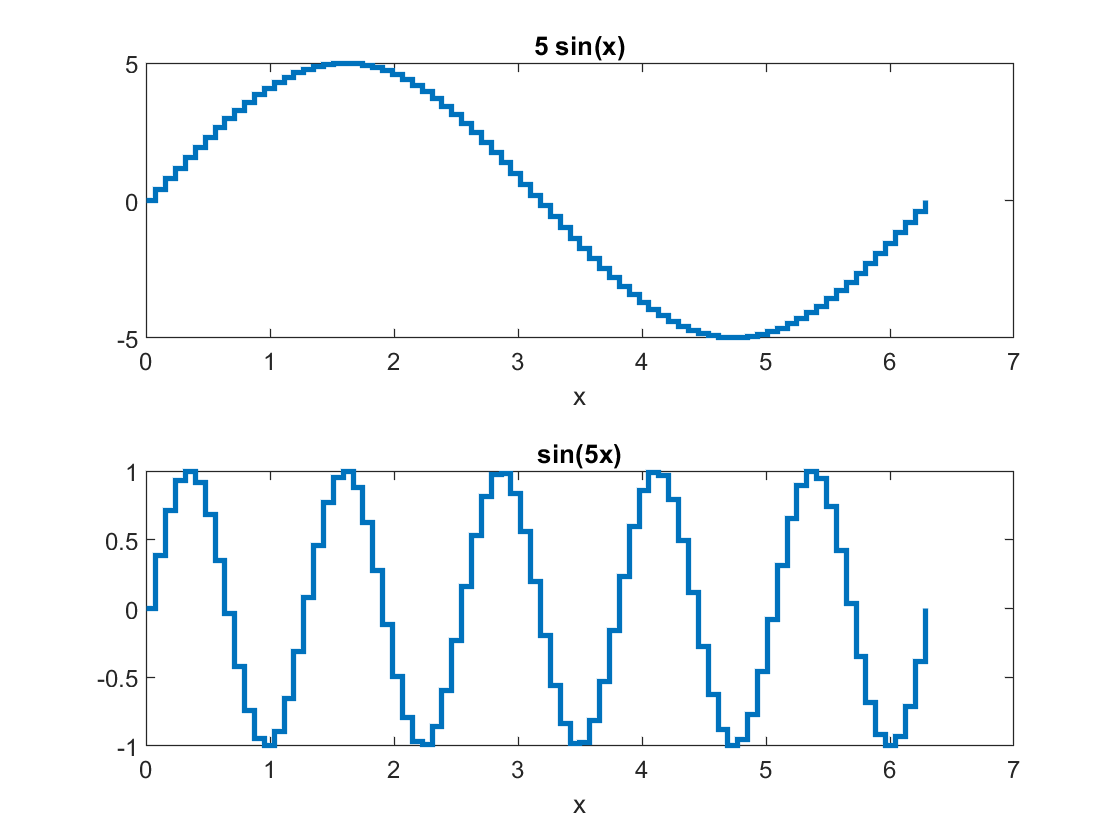

figure
tiledlayout(2,1)
% Top plot
ax1 = nexttile;
s1 = stairs(ax1,x,y1,"LineWidth",2);
title("5 sin(x)")
xlabel("x")

% Bottom plot
ax2 = nexttile;  
s2 = stairs(ax2,x,y2,"LineWidth",2);
title("sin(5x)")
xlabel("x")

## **Additional Information**

### **Get All Stair Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Stair object, uncomment the following code. View or modify these properties using dot notation.

% get(s)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[stairs](https://www.mathworks.com/help/matlab/ref/stairs.html)

### Helper Functions

This function generates discrete sine function data.

function [x,y1,y2] = createData()   
    x = linspace(0,2*pi,80);
    y1 = 5*sin(x);
    y2 = sin(5*x);
end

Copyright (c) 2021, The MathWorks, Inc.